**Oefening 5.1 - RRPRRR Stanford arm**

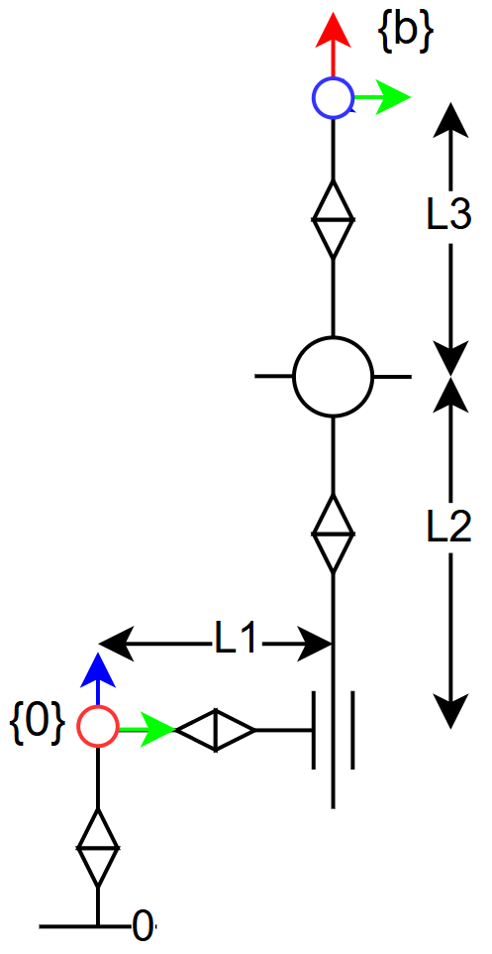

1.Mechanisch: L1 = 0.5 ; L2 = 2 ; L3 = 0.1 (idem Oef. 4.1.3)

2.Stel de ruimtelijke- enlichaams-Jacobiaanvan het eindeffectorpunt(Borg)opindeconfiguraties:

    1.Theta_cfg1= [0; 0; 0.5; 0 ; **pi****/2 **; 0]

    2.Theta_cfg2 = [0; 0; 0.5; 0 ; **0.1**   ; 0]

3.Wat is de v enω manipuleerbaarheidsindexin beide cfgs? Bereken:

    1.v-ellipsoidenin frame {0} (dus met ruimt. J)

    2.ω– ellipsoidenin frame {b} (dus met lich. J)

4.Welke ω-richting heeftin cfg2 de slechtste manipuleerbaarheid? (geefrichtingsvectorin {0} én in {b}, Tip: R)

clear; clc;
% Symbolische lengtes en gewrichtscoordinaten

% Home-configuratie M: eindeffectorframe {b} t.o.v. {0}

$$M = \left(\begin{array}{cccc} 0 & 0 & -1 & 0\\ 0 & 1 & 0 & L_{1}\\ 1 & 0 & 0 & L_{2}+L_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

%M =

% Gewrichtstype (r/p), asrichting s en punt q op elke as
% jtype = {'r', 'r', 'p', 'r','r', 'r'}

jtype = 1×6 cell array
    {'r'}    {'r'}    {'p'}    {'r'}    {'r'}    {'r'}


% s={[0;0;1], etc};
% q={[0;0;0], etc}; % (eenvoudige punten op schroefassen

% Schroefassen in het ruimteframe {0}
% S=cell(1,6);
% for i=1:6
%     switch jtype{i}
%         case 'r'
%                 S{i} = [????]; % rotatie: v = q x s
%         case 'p'
%                 S{i} = [????]; % prismatisch: enkel v
%     end
% end

% Cell array omvormen naar double matrix
% Slist = [S{:}]

$$Slist = \left(\begin{array}{cccccc} 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 1 & 0\\ 1 & 0 & 0 & 1 & 0 & 1\\ 0 & 0 & 0 & L_{1} & -L_{2} & L_{1}\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0 & 0 \end{array}\right)$$


% Numerieke waarden invullen
% Llist_num = [mech parameters]

Llist_num =     0.5000    2.0000    0.1000


% Slist_num = double(subs(Slist,[???],Llist_num));

%M_num = double(subs(M,[????],Llist_num));

% Twee te vergelijken numerieke configuraties
% thetalist_1 = [???];
% thetalist_2 = [???]]; % bijna polssingulariteit

% Voorwaartse kinematica
% T1 =
% T2 =

% Ruimtelijke Jacobianen

Js1 =          0         0         0         0         0    1.0000
         0    1.0000         0         0    1.0000         0
    1.0000         0         0    1.0000         0    0.0000
         0         0         0    0.5000   -2.5000    0.0000
         0         0         0         0         0    2.5000
         0         0    1.0000         0         0   -0.5000


Js2 =          0         0         0         0         0    0.0998
         0    1.0000         0         0    1.0000         0
    1.0000         0         0    1.0000         0    0.9950
         0         0         0    0.5000   -2.5000    0.4975
         0         0         0         0         0    0.2496
         0         0    1.0000         0         0   -0.0499



% Lichaams-Jacobianen: Jb = Ad(T^-1) * Js

Jb1 =     0.0000         0         0    0.0000         0    1.0000
         0    1.0000         0         0    1.0000         0
    1.0000         0         0    1.0000         0         0
   -0.5000    2.5000    0.0000         0         0         0
    0.1000         0         0    0.1000         0         0
    0.0000   -0.1000    1.0000         0   -0.1000         0


Jb2 =     0.9950         0         0    0.9950         0    1.0000
         0    1.0000         0         0    1.0000         0
    0.0998         0         0    0.0998         0    0.0000
   -0.0499    0.2496    0.9950         0    0.0000   -0.0000
    0.0100         0         0    0.0100         0   -0.0000
    0.4975   -2.5875    0.0998         0   -0.1000         0



% v-ellipsoides in {0} (lineair), 

melv_s1 = struct with fields:
          axes: [3×3 double]
         radii: [3×1 double]
             A: [3×3 double]
             w: 6.3738
    sqrt_minSV: 0.9772
       sqrt_cd: 2.6180


melv_s2 = struct with fields:
          axes: [3×3 double]
         radii: [3×1 double]
             A: [3×3 double]
             w: 0.6363
    sqrt_minSV: 0.2446
       sqrt_cd: 10.6213


melom_b1 = struct with fields:
          axes: [3×3 double]
         radii: [3×1 double]
             A: [3×3 double]
             w: 2.0000
    sqrt_minSV: 1
       sqrt_cd: 1.4142


melom_b2 = struct with fields:
          axes: [3×3 double]
         radii: [3×1 double]
             A: [3×3 double]
             w: 0.1997
    sqrt_minSV: 0.0816
       sqrt_cd: 21.2014


% melv_s1=manipulabilityEllipsoid(???)
% melv_s2=anipulabilityEllipsoid(???)

% omega-ellipsoides in {b} (angulair)
% melom_b1=anipulabilityEllipsoid(???)
% melom_b2=anipulabilityEllipsoid(???)

% Samenvoegen in struct array voor eenvoudige vergelijking
% allmels = [melv_s1,melv_s2,melom_b1,melom_b2]

allmels = 1×4 struct array with fields:
    axes
    radii
    A
    w
    sqrt_minSV
    sqrt_cd



% zoek de "slechte" as in melom_b2

bad_direction_omega_cfg2 =     0.9994
         0
   -0.0333


•Visualiseer de manipuleerbaarheidsellipsoïdes

•Plot eventueelbeidecfgsin een enkel {0}-figuur.(zie hiernaast)

•Op een{0}-figuur plot de v-ellipsen, gecentreerdin de oorsprong (van {0}). Vergelijk XZ enXY aanzicht.

•Op een{b}-figuur plot de ω-ellipsen gecentreerdin de oorsprong (van {b}). Wat valt op?

%% Plot poses
% Wereldframe {0} en beide eindeffectorposes
figure;
plotFrame(eye(3)*0.6,zeros(3,1));

hold on
plotFrame(T1,0);

plotFrame(T2,0);

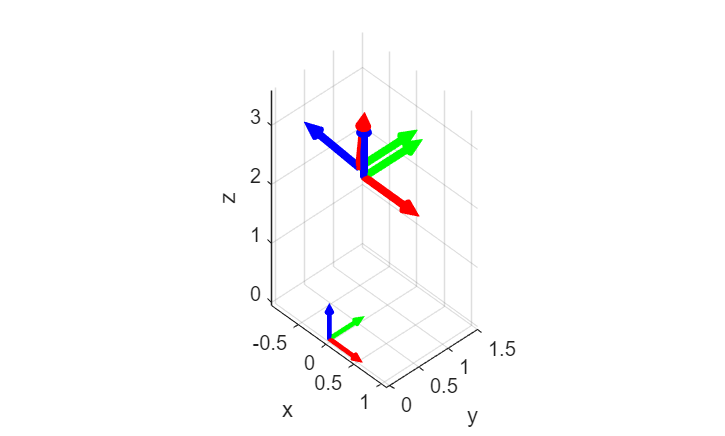

view([46.667 42.667])
axis equal
hold off


%% Plot v-ellipsoid in space-coord
% Beide v-ellipsoides gecentreerd in de oorsprong van {0}
figure
axis equal
plotFrame(eye(3)*0.6,zeros(3,1))

ans =     0.6000
         0
         0


hold on
plotEllipsoid(melv_s1,[0;0;0])

ans =   Surface (manipulabilityEllipsoid) with properties:

       EdgeColor: 'none'
       LineStyle: '-'
       FaceColor: [0.0660 0.4430 0.7450]
    FaceLighting: 'flat'
       FaceAlpha: 0.3000
           XData: [41×41 double]
           YData: [41×41 double]
           ZData: [41×41 double]
           CData: [41×41 double]

  Show all properties


plotEllipsoid(melv_s2,[0;0;0])

ans =   Surface (manipulabilityEllipsoid) with properties:

       EdgeColor: 'none'
       LineStyle: '-'
       FaceColor: [0.8660 0.3290 0]
    FaceLighting: 'flat'
       FaceAlpha: 0.3000
           XData: [41×41 double]
           YData: [41×41 double]
           ZData: [41×41 double]
           CData: [41×41 double]

  Show all properties


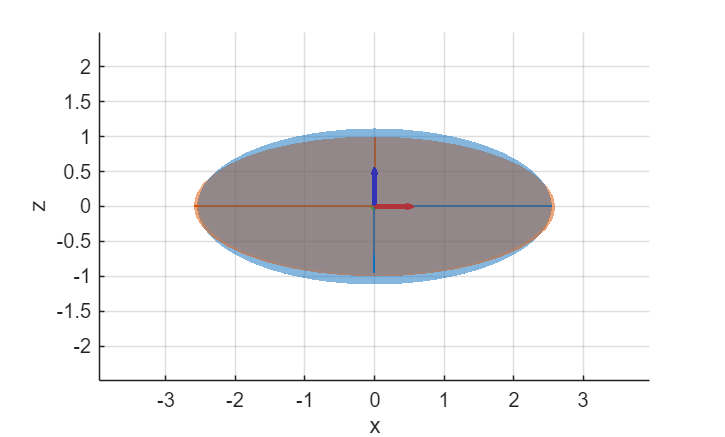

view([0 0])
hold off


%% v-ellipsoid: XY-, YZ- en XZ-aanzicht
% Zelfde inhoud als vorige figuur, in drie orthogonale aanzichten
figure('Position', [100 100 950 340])
vw = [0 90; 90 0; 0 0];   % kijkrichtingen: XY, YZ, XZ
nm = {'XY','YZ','XZ'};
for k = 1:3
    subplot(1,3,k)
    plotFrame(eye(3)*0.6,zeros(3,1));
    hold on
    plotEllipsoid(melv_s1,[0;0;0]);
    plotEllipsoid(melv_s2,[0;0;0]);
    hold off
    view(vw(k,:))
    title([nm{k} '-aanzicht'])
end

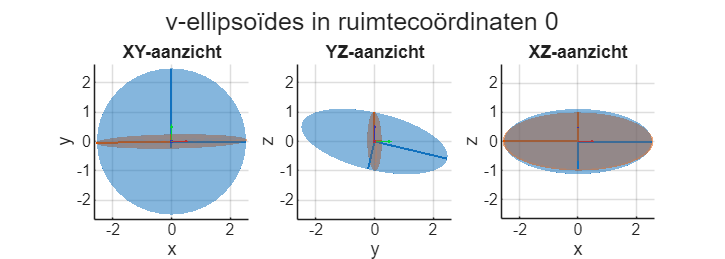

% Krappe, identieke asgrenzen: grootste uitwijking langs de assen
r = 1.02 * sqrt(max([diag(melv_s1.A); diag(melv_s2.A)]));
axs = findall(gcf,'Type','axes');
set(axs,'XLim',[-r r],'YLim',[-r r],'ZLim',[-r r], ...
    'DataAspectRatio',[1 1 1],'PlotBoxAspectRatio',[1 1 1]);
sgtitle('v-ellipsoïdes in ruimtecoördinaten {0}')


%% Plot omega-ellipsoid in body-coord
% Beide omega-ellipsoides in lichaamscoordinaten; cfg2 nadert polssingulariteit
figure
axis equal
plotFrame(eye(3)*0.6,zeros(3,1))

ans =     0.6000
         0
         0


hold on
plotEllipsoid(melom_b1,[0;0;0])

ans =   Surface (manipulabilityEllipsoid) with properties:

       EdgeColor: 'none'
       LineStyle: '-'
       FaceColor: [0.0660 0.4430 0.7450]
    FaceLighting: 'flat'
       FaceAlpha: 0.3000
           XData: [41×41 double]
           YData: [41×41 double]
           ZData: [41×41 double]
           CData: [41×41 double]

  Show all properties


plotEllipsoid(melom_b2,[0;0;0])

ans =   Surface (manipulabilityEllipsoid) with properties:

       EdgeColor: 'none'
       LineStyle: '-'
       FaceColor: [0.8660 0.3290 0]
    FaceLighting: 'flat'
       FaceAlpha: 0.3000
           XData: [41×41 double]
           YData: [41×41 double]
           ZData: [41×41 double]
           CData: [41×41 double]

  Show all properties


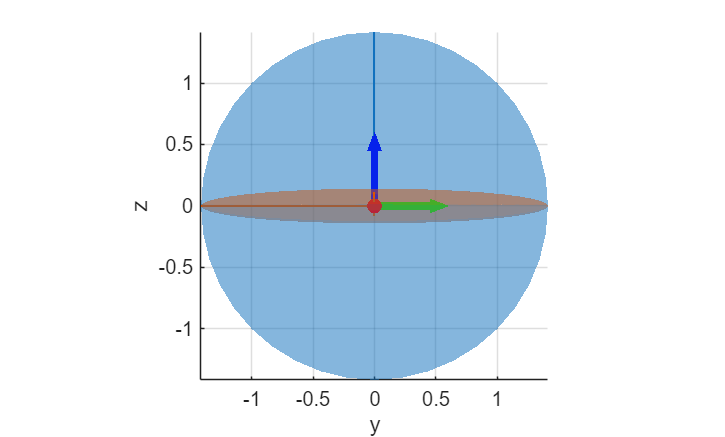

view([90 0])
hold off


%% omega-ellipsoid: XY-, YZ- en XZ-aanzicht
% Zelfde inhoud als vorige figuur, in drie orthogonale aanzichten
figure('Position', [100 100 950 340])
vw = [0 90; 90 0; 0 0];   % kijkrichtingen: XY, YZ, XZ
nm = {'XY','YZ','XZ'};
for k = 1:3
    subplot(1,3,k)
    plotFrame(eye(3)*0.6,zeros(3,1));
    hold on
    plotEllipsoid(melom_b1,[0;0;0]);
    plotEllipsoid(melom_b2,[0;0;0]);
    hold off
    view(vw(k,:))
    title([nm{k} '-aanzicht'])
end

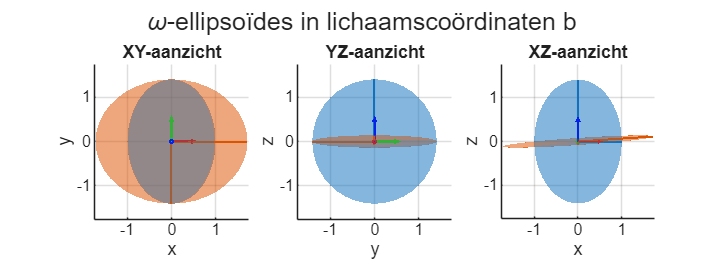

% Krappe, identieke asgrenzen: grootste uitwijking langs de assen
r = 1.02 * sqrt(max([diag(melom_b1.A); diag(melom_b2.A)]));
axs = findall(gcf,'Type','axes');
set(axs,'XLim',[-r r],'YLim',[-r r],'ZLim',[-r r], ...
    'DataAspectRatio',[1 1 1],'PlotBoxAspectRatio',[1 1 1]);
sgtitle('\omega-ellipsoïdes in lichaamscoördinaten {b}')